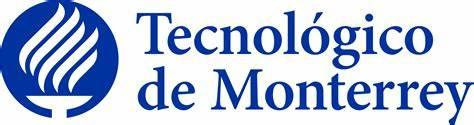

**Actividad 1 velocidades lineales y angulares.**

**Fundamentación de robótica gpo101**

**Hecho por:**

A01736196 | Abraham Ortiz Castro

 ITESM puebla

**Profesor:**

Alfredo García Suárez.

*22 de febrero del 2024.*

## Explicación de código.

Se empieza poniendo comandos básicos para poder borrar todas las variables, cerrar todas las ventanas y limpiar el comand window.

close all
clc

Se declaran las variables simbólicas para poder trabajar con ellas.

syms th1(t) l1 t th2(t) l2

Se deben de declarar la configuración del robot, en este caso se tienen dos grados y ambos son rotacionales, por lo tanto se ponen dos ceros.

RP = [0 0];

Se debe de generar el vector de coordenadas articulares, esto para tener la referencia de cuales son las partes movibles del robot.

Q=[th1 th2];
disp('Coordenadas particulares');

Coordenadas particulares


pretty(Q)

(th1(t), th2(t))



Se crea el vector de velocidades, recordando que la derivada de la posición es la velocidad, lo único que se debe de hacer es derivar el vector Q

Qp = diff(Q,t);
disp('Velocidades particulares ');

Velocidades particulares 


pretty(Qp);

/  d          d        \
| -- th1(t), -- th2(t) |
\ dt         dt        /



Para poder calcular los grados de libertad se le puede calcular la longuitud al vector RP debido a que se ha definido todos los grados existentes en el, por lo tanto devolverá el valor de los números de los grados de libertad. De la misma manera se debe de convertir en string para cuando se le quiera hacer display en pantalla.

%Numero de grados de libertad
GDL = size(RP,2);
GDL_str = num2str(GDL);

Los vectores de translación se han sacado con ayuda de la geometría.

Para el vector de translación 1 se tiene la referencia del eje x será el cateto adyacente, por lo tanto al tener l1 (lo que mide el brazo) y de la misma manera se tendrá el ángulo del brazo, por lo tanto ya que cos(tetha)=x/l1, se puede obtener x de esa fórmula. Para sacar y se sigue la misma lógica pero con el seno, ya que se quiere obtener el cateto opuesto (y). La función sería sin(tetha)=y/l1 y se puede obtener facilmente y. Con esta explicación se puede tener lo siguiente.

P(:,:,1) = [l1*cos(th1); l1*sin(th1);0];

En el caso del segundo punto se sigue la misma lógica, pero se debe de tener en cuenta que es una extensión del primero, por lo tanto se le debe de hacer una suma del anterior resultado y de la misma maner al momento de poner los ángulos, ya que el ángulo del segundo punto dependerá del primero, de la misma manera se requieren sumar para obtener la posición final del brazo.

P(:,:,2) = [l1*cos(th1)+l2*cos(th2+th1); 
            l1*sin(th1)+l2*sin(th2+th1);
            0];

Para la matriz de rotación se debe de tomar en cuenta que al momento de hacer el análisis se observa que la rotación será sobre el eje z, ya que ambos grados se comportan de la misma manera, son exactamente iguales, por lo tanto queda de la siguiente manera.

%Matriz de rotación
R(:,:,1)= [cos(th1) -sin(th1) 0;
           sin(th1)  cos(th1) 0;
           0         0        1];
R(:,:,2)= [cos(th1) -sin(th1) 0;
           sin(th1)  cos(th1) 0;
           0         0        1];

Ya se tiene el análisis de la rotación y el de translación, para poder hacer una matriz cuadrada se requiere de un vector de ceros transpuesto.

%Vector de ceros
Vector_zeros = zeros(1,3);

Después de esto se deben de incializar las matrices de transformación homogenea locales (de cada punto del robot.)

%Inicializamos las matrices de transformación homogenea locales
A(:,:,GDL) = simplify([R(:,:,GDL) P(:,:,GDL); Vector_zeros 1]);

Después hacer las matrices globales, la diferencia en este caso es que en estas se estarán multiplicando de manera ordenada así llegando hasta el último grado de libertad, por ejemplo el primero por el segundo; el resultado obtenido del primero por el segundo multiplicarlo por el tercero y así n veces.

%Globales
T(:,:,GDL) = simplify([R(:,:,GDL) P(:,:,GDL); Vector_zeros 1]);


Se inicializa matriz de posición y de rotación.

P0(:,:,GDL) = P(:,:,GDL);

R0(:,:,GDL) = R(:,:,GDL);

Se debe de realizar el ciclo for el cual se repetira GDL veces, lo primero que se debe de hacer es poner la matriz local para después poderla multiplicar por la n-1 del grado, en el caso de que sea el primero lo que hace es quedarse como la local. Al final se desplega cada grado tanto local como general en el command window y se guardan las matrices de rotación y de posición.

for i= 1:GDL
    i_str = num2str(i);
    %Locales
    disp(strcat('Matriz de transformación local ', i_str));
    A(:,:,i)= simplify([R(:,:,i) P(:,:,i); Vector_zeros 1]);
    pretty(A(:,:,i));

    %Globales
    try
        T(:,:,i) = T(:,:,i-1)*A(:,:,i);
    catch
        T(:,:,i) = A(:,:,i);
    end

    disp(strcat('Matriz de transformación global ', i_str));
    T(:,:,i) = simplify(T(:,:,i));
    pretty(T(:,:,i));

    %Se obtiene la matriz de rotación 
    R0(:,:,i) = T(1:3,1:3,i); 
    P0(:,:,i) = T(1:3,4,i); 
    pretty(R0(:,:,i))
    pretty(P0(:,:,i))
end

Matriz de transformación local1


/ cos(th1(t)), -sin(th1(t)), 0, l1 cos(th1(t)) \
|                                              |
| sin(th1(t)),  cos(th1(t)), 0, l1 sin(th1(t)) |
|                                              |
|      0,            0,      1,        0       |
|                                              |
\      0,            0,      0,        1       /



Matriz de transformación global1


/ cos(th1(t)), -sin(th1(t)), 0, l1 cos(th1(t)) \
|                                              |
| sin(th1(t)),  cos(th1(t)), 0, l1 sin(th1(t)) |
|                                              |
|      0,            0,      1,        0       |
|                                              |
\      0,            0,      0,        1       /



/ cos(th1(t)), -sin(th1(t)), 0 \
|                              |
| sin(th1(t)),  cos(th1(t)), 0 |
|                              |
\      0,            0,      1 /



/ l1 cos(th1(t)) \
|                |
| l1 sin(th1(t)) |
|                |
\        0       /



Matriz de transformación local2


/ cos(th1(t)), -sin(th1(t)), 0, l1 cos(th1(t)) + l2 cos(th1(t) + th2(t)) \
|                                                                        |
| sin(th1(t)),  cos(th1(t)), 0, l1 sin(th1(t)) + l2 sin(th1(t) + th2(t)) |
|                                                                        |
|      0,            0,      1,                     0                    |
|                                                                        |
\      0,            0,      0,                     1                    /



Matriz de transformación global2


/ #2, -#1, 0, l1 cos(th1(t)) + l1 cos(2 th1(t)) + l2 cos(2 th1(t) + th2(t)) \
|                                                                           |
| #1,  #2, 0,       l1 sin(th1(t)) + l1 #1 + l2 sin(2 th1(t) + th2(t))      |
|                                                                           |
|  0,  0,  1,                               0                               |
|                                                                           |
\  0,  0,  0,                               1                               /

where

   #1 == sin(2 th1(t))

                          2
   #2 == 1 - 2 sin(th1(t))




/                  2                        \
| 1 - 2 sin(th1(t)) ,   -sin(2 th1(t)),   0 |
|                                           |
|                                      2    |
|    sin(2 th1(t)),   1 - 2 sin(th1(t)) , 0 |
|                                           |
\          0,                  0,         1 /



/ l1 cos(th1(t)) + l1 cos(2 th1(t)) + l2 cos(2 th1(t) + th2(t)) \
|                                                               |
| l1 sin(th1(t)) + l1 sin(2 th1(t)) + l2 sin(2 th1(t) + th2(t)) |
|                                                               |
\                               0                               /



En la siguiente sección lo que se va a hacer es calcular el jacobiano lineal y angular de manera analítica. Ya existen unas fórmulas preestablecidas, por lo tanto solamente hay que poner los condicionales para que haga la operación dependiendo sea el caso. Las operaciones son las siguientes:

Para lineal.

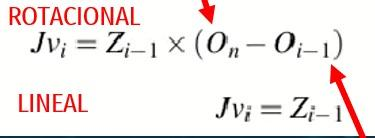

Para angular.

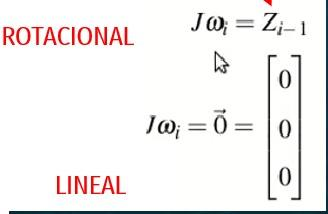

Esto se mete en el código for y queda de la siguiente manera

for k= 1:GDL
    if((RP(k) == 0) | (RP(k) == 1))
        try
            Jv_a(:,k) = cross(RO(:,3,k-1), P0(:,:,GDL)-P0(:,:,k-1));
            Jw_a(:,k) = R0(:,3,k-1);
        catch
            Jv_a(:,k) = cross([0,0,1], P0(:,:,GDL));
            Jw_a(:,k) = [0,0,1];
        end

    else
        try
            Jv_a(:,k) = R0(:,3,k-1);
        catch
            Jv_a(:,k) = [0,0,1];

        end
            Jw_a(:,k)=[0,0,0];
    end
end


Se muestran en el command window los jacobianos.

Jv_a = simplify(Jv_a);
Jw_a = simplify(Jw_a);
disp('Jacobiano lineal')

Jacobiano lineal


pretty(Jv_a)

/ #1, #1 \
|        |
| #2, #2 |
|        |
\  0,  0 /

where

   #1 == - l1 sin(th1(t)) - l1 sin(2 th1(t)) - l2 sin(2 th1(t) + th2(t))

   #2 == l1 cos(th1(t)) + l1 cos(2 th1(t)) + l2 cos(2 th1(t) + th2(t))




disp('Jacobiano angular')

Jacobiano angular


pretty(Jw_a)

/ 0, 0 \
|      |
| 0, 0 |
|      |
\ 1, 1 /



Al final, solamente se requiere multiplicar el jacobiano por q punto (la diferencial respecto al tiempo de q) para obtener la velocidad del robot.

disp('Velocidad lineal')

Velocidad lineal


V = simplify(Jv_a*Qp');
pretty(V)

/ -#1 (l1 sin(th1(t)) + l1 sin(2 th1(t)) + l2 sin(2 th1(t) + th2(t))) \
|                                                                     |
|  #1 (l1 cos(th1(t)) + l1 cos(2 th1(t)) + l2 cos(2 th1(t) + th2(t))) |
|                                                                     |
\                                  0                                  /

where

         _________   _________
          d           d
   #1 == -- th1(t) + -- th2(t)
         dt          dt




disp('Velocidad angular')

Velocidad angular


W = simplify(Jw_a*Qp');
pretty(W)

/           0           \
|                       |
|           0           |
|                       |
| _________   _________ |
|  d           d        |
| -- th1(t) + -- th2(t) |
\ dt          dt        /



## Análisis de resultados.

Los resultados de la velocidad lineal y angular se me hacen lógicos, ya que no va a existir un desplazamiento en z lineal por lo tanto este debería de ser 0, de la misma manera en los resultados se está incluyendo el diferencial de ambos angulos y de la mismia manera la suma de ángulos en un mismo argumento de la función senosoidal de l2 e igual incluye ambas medidas de los brazos dentro de la fórmula. Por lo tanto está haciendo una buena relación de ambos grados de libertad, suena geometricamente lógico de la misma manera.

Hablando de la velocidad angular se hace muy lógica que solamente sea diferente de 0 en z, debido a que es el único eje en el que está rotando, por lo tanto no hay razón para que tenga dezplazamiento angular en x y y. De la misma manera tiene sentido que esté incluyendo ambos diferenciales, tanto el de th1 y el de th2. Porque significa que realizó una relación de ambos grados.

En conclusión los resultados tienen sentido y son lógicos según el análisis del brazo de dos grados de libertad.